# Lecture 10/18

**spatial domain**

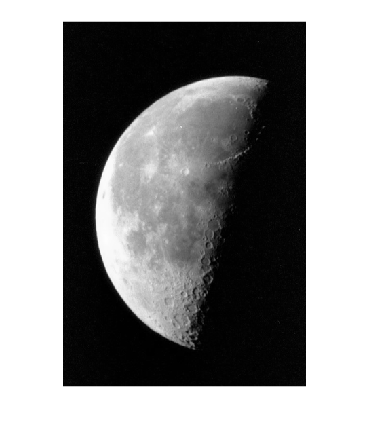

img = im2double(imread("moon.tif"));
figure; imshow(img);

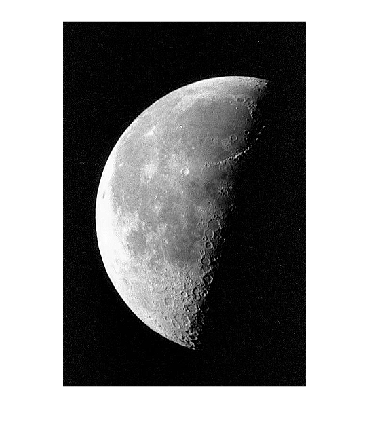


img =  img(:,:,1);

% laplacian filter
filter = [0 -1 0;-1 4 -1;0 -1 0];   
img_f = conv2(img, filter, "same");
img_f = img + img_f;
figure; imshow(img_f);

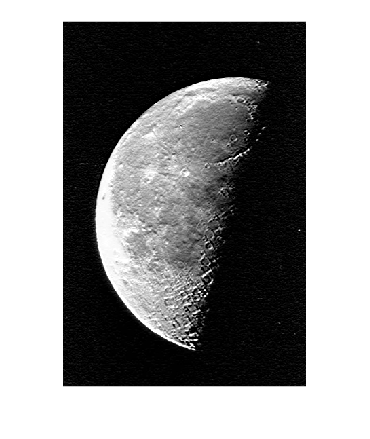


% sobel filter
sobel = [-1 -2 -1;0 0 0;1 2 1];
img_f = conv2(img, sobel, "same");
img_f = img + img_f;
figure; imshow(img_f);

**frequency domain**

exercise II, III

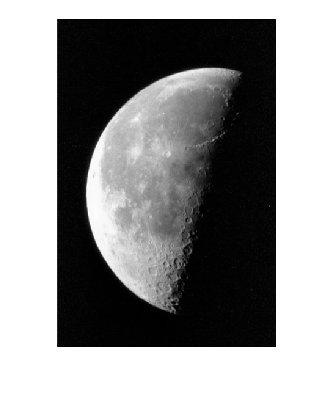

img = im2double(imread("moon.tif", "tif"));
figure; imshow(img);

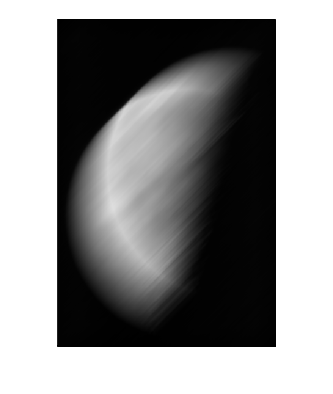

% imfilter
h = fspecial('motion', 100, 45);
f = imfilter(img, h);
figure; imshow(f);

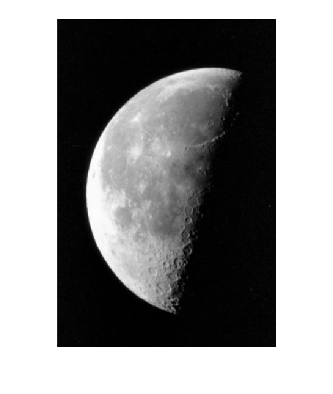

% low pass filter
lpass = fspecial('gaussian', [3 3]);
lowpass = imfilter(img, lpass);
figure; imshow(lowpass);

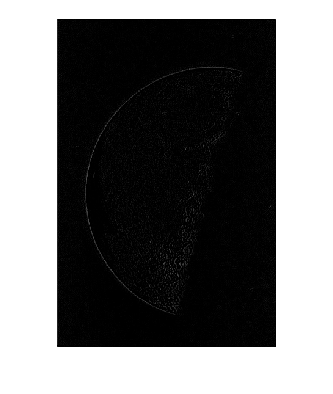

% high pass filter
hpass = fspecial("laplacian");
highpass = imfilter(img, hpass);
figure; imshow(highpass);

% unsharp masking

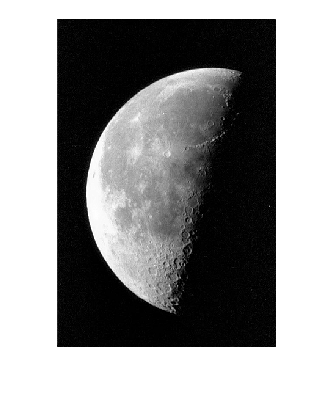

w = 4;
unsharp = img + w*(img - lowpass);
figure; imshow(unsharp);

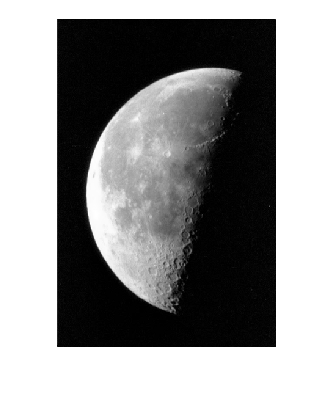

% high boost
A = 5;
hb = A*img - lowpass;
hb = hb/max(hb(:));
figure; imshow(hb);